%(*@\draftcomment{the prefix for every sub-heading in this script is "homogenisation"}@*)
folderPath = 'D:\TechnicalReport\nTop Homogenisation';
files = dir(fullfile(folderPath, '*.csv'));
fileNames = {files.name};

blue   = [0, 0.4470, 0.7410]; % "#0072BD"
cyan  = [0.3010, 0.7450, 0.9330]; % "#4DBEEE"
red = [0.8500, 0.3250, 0.0980]; % "#D95319"
yellow = [0.9290, 0.6940, 0.1250]; % "#EDB120"

% extract numeric values from fileNames
numericValues = zeros(length(fileNames), 1);
for i = 1:length(fileNames)
    [~, name, ~] = fileparts(fileNames{i});  % remove .csv extension
    numericValues(i) = str2double(name);
end

% sort based on number
[~, sortedIndices] = sort(numericValues);
sortedFilenames = fileNames(sortedIndices);

% data from CSV files in sorted order
tables = cell(length(sortedFilenames), 1);
for i = 1:length(sortedFilenames)
    filePath = fullfile(folderPath, sortedFilenames{i});
    tables{i} = readtable(filePath);
    tables{i,2} = numericValues(sortedIndices(i)) * 100; % convert to percentage
end

densities = vertcat(tables{:,2});

% Extract infill densities and stiffness matrices
numFiles = length(tables);
densities = zeros(numFiles, 1);
stiffnessData = zeros(numFiles, 6, 6); % 3D array: [density, row, col]

for i = 1:numFiles
    densities(i) = tables{i,2};        % Get density from second column
    currentTable = tables{i,1};       % Get 6x6 table from first column
    stiffnessData(i, :, :) = currentTable{:,:}; % Convert table to numeric array
end

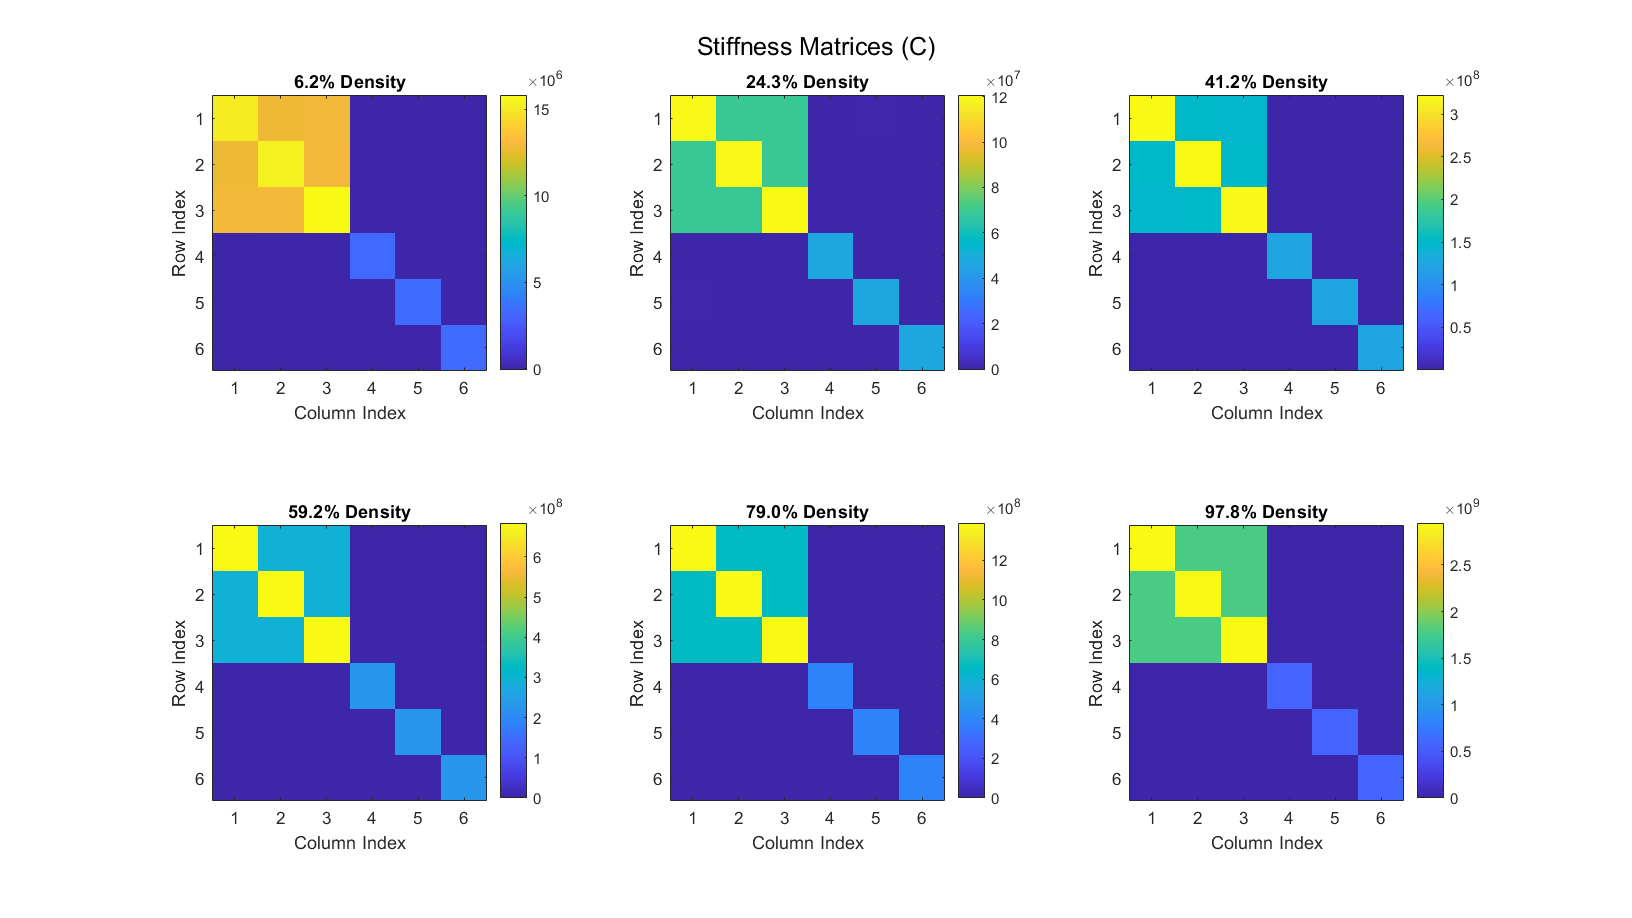

%(*@\codesubsection{Stiffness Matrix Heatmaps}{homogenisation-stiffness-matrix-heatmaps}@*)
numFiles = numel(sortedFilenames);
numSteps = 6;
selected_indices = round(linspace(1, numFiles, min(numFiles,numSteps)));

nCols = ceil(sqrt(numSteps));
nRows = ceil(numSteps / nCols);  
cFigure;
for j = 1:length(selected_indices)
    idx = selected_indices(j);
    subplot(nRows,nCols,j);

    imagesc(squeeze(stiffnessData(idx, :, :))); % create heatmap
    colorbar;
    axis square;
    xlabel('Column Index');
    ylabel('Row Index');
    title(sprintf('%.1f%% Density', densities(idx)));
    set(gca, 'XTick', 1:6, 'YTick', 1:6);
end
sgtitle('Stiffness Matrices (C)');

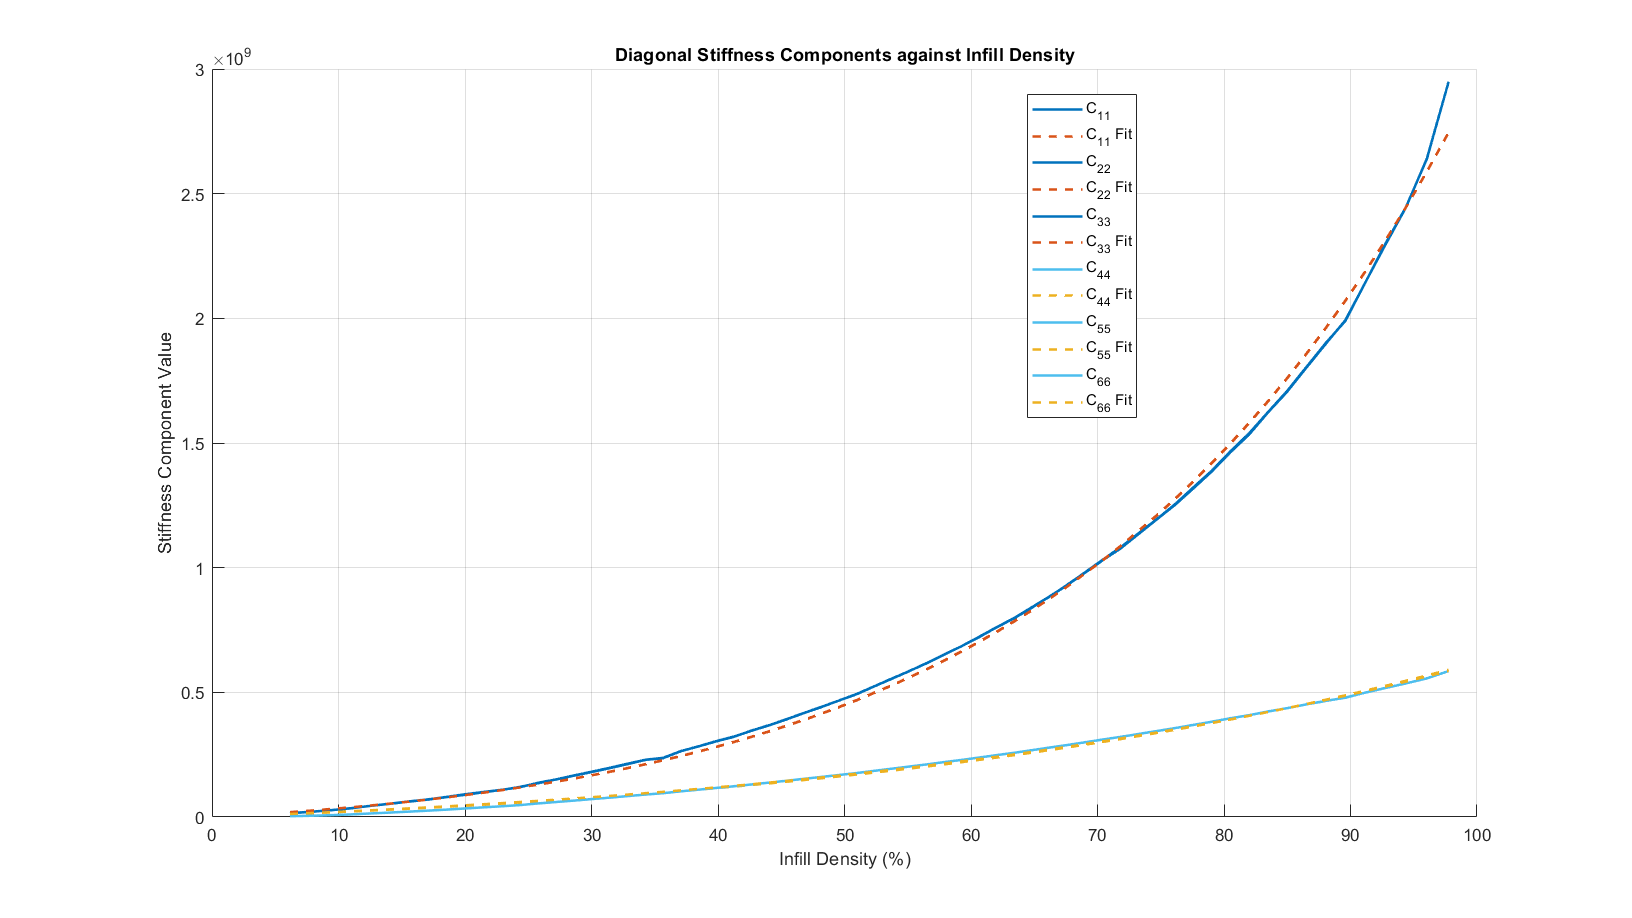

%(*@\codesubsection{Exponential Regression}{homogenisation-stiffness-exponential-regression}@*)
cFigure;
hold on;

% preallocate
fitResults = cell(6,1); % stores (a, b, R^2)

for diagIdx = 1:6
    x = densities(:);
    y = squeeze(stiffnessData(:, diagIdx, diagIdx));
    y = y(:);
    
    % original data
    if ismember(diagIdx, [1, 2, 3])
        colour = blue;
    else
        colour = cyan;
    end

    plot(x, y, 'LineWidth', 1.5, 'DisplayName', sprintf('C_{%d%d}', diagIdx, diagIdx),'Color',colour);
    

    % using custom exponential model y = a*x*exp(b*x) to ensure 0 crossing
    ft = fittype('a*x*exp(b*x)', 'independent', 'x', 'dependent', 'y');
    
    % linear initial guess (estimating to ensure convergence)
    valid = (x > 0) & (y > 0);
    if sum(valid) >= 2
        xValid = x(valid);
        yValid = y(valid);
        z = log(yValid) - log(xValid);
        X = [ones(size(xValid)), xValid];
        coeffs = X \ z;
        logAInit = coeffs(1);
        bInit = coeffs(2);
        aInit = exp(logAInit);
    end
    
    [fitResult, gof] = fit(x, y, ft, 'StartPoint', [aInit, bInit]);
    
    fitResults{diagIdx} = struct('a', fitResult.a, 'b', fitResult.b, 'Rsquare', gof.rsquare);
    
    % plot fitted curves
    if ismember(diagIdx, [1, 2, 3])
        colour = red;
    else
        colour = yellow;
    end

    plot(x, fitResult(x), '--', 'LineWidth', 1.5, 'DisplayName', sprintf('C_{%d%d} Fit', diagIdx, diagIdx),'Color',colour);
end

xlabel('Infill Density (%)');
ylabel('Stiffness Component Value');
title('Diagonal Stiffness Components against Infill Density');
legend('Location', 'best');
grid on;


% compile results into table
componentNames = cell(6,1); aValues = zeros(6,1);
bValues = zeros(6,1); r2Values = zeros(6,1);

for diagIdx = 1:6
    componentNames{diagIdx} = sprintf('C_{%d%d}', diagIdx, diagIdx);
    if isstruct(fitResults{diagIdx})
        res = fitResults{diagIdx};
        aValues(diagIdx) = res.a;
        bValues(diagIdx) = res.b;
        r2Values(diagIdx) = res.Rsquare;
    else
        aValues(diagIdx) = NaN;
        bValues(diagIdx) = NaN;
        r2Values(diagIdx) = NaN;
    end
end

resultsTable = table(componentNames, aValues, bValues, r2Values, 'VariableNames', {'Component', 'a', 'b', 'R2'});
disp(resultsTable);

    Component         a            b          R2   
    __________    __________    ________    _______

    {'C_{11}'}    2.7178e+06    0.023887    0.99758
    {'C_{22}'}    2.7317e+06    0.023839    0.99763
    {'C_{33}'}    2.7244e+06    0.023864    0.99762
    {'C_{44}'}    1.7663e+06    0.012568    0.99785
    {'C_{55}'}    1.7518e+06    0.012666    0.99779
    {'C_{66}'}    1.8422e+06    0.012067    0.99802



%(*@\codesubsection{Save Figures}{homogenisation-save-figures}@*)
saveFigures(folderPath,true,0);